# Lab - Numerical Differentiation

**Topics: **analytical differentiation using MATLAB, forward, backward and centered finite difference formulas, Richardson extrapolation for differentiation

## Set up system

clear, clc, format compact

The velocity (m/s) of an object at time t seconds is given by $v=\frac{2t}{\sqrt{1+t^2 }}\;$ Using Richardson's extrapolation, find the acceleration of the particle at time t = 5s using h = 0.5 and 0.25. Employ the exact solution to compute the true percent relative error of each estimate

v = @(t) 2*t./sqrt(1+t.^2);
ti = 5;


## **Analytical differentiation**

syms t
V(t) = 2*t/sqrt(1+t^2);
acceration = diff(V)

$$acceration(t) = \frac{2}{\sqrt{t^{2}+1}}-\frac{2\,t^{2}}{{\left(t^{2}+1\right)}^{3/2}}$$

accel_exact = double(acceration(ti))

accel_exact = 0.0151


PRTE = @(estimate) (accel_exact - estimate)./accel_exact*100;

## O(h^2) centered finite-difference, coarse h=0.5

h = 0.5;
tiplus1 = ti + h;
timinus1 = ti - h;
accel_centered_coarse = (v(tiplus1)-v(timinus1))/(2*h)

accel_centered_coarse = 0.0154

PRTE_centered = PRTE(accel_centered_coarse)

PRTE_centered = -1.8550

## O(h^2) centered finite-difference, fine h=0.25

h = 0.25;
tiplus1 = ti + h;
timinus1 = ti - h;
accel_centered_fine = (v(tiplus1)-v(timinus1))/(2*h)

accel_centered_fine = 0.0152

PRTE_centered = PRTE(accel_centered_fine)

PRTE_centered = -0.4592

## Richardson extrapolation


$$D=\frac{4}{3}D\left(h_2 \right)-\frac{1}{3}D\left(h_1 \right)$$



accel_richard = 4/3*accel_centered_fine-1/3*accel_centered_coarse

accel_richard = 0.0151

PRTE_richard = PRTE(accel_richard)

PRTE_richard = 0.0061

## Results display

Headings = ["Method", "Order", "h", "Derivative", "PRTE"];
Methods = ["Analytical", "Centered", ...
    "Centered", "Richardson"];
Orders = ["N/A", "2", "2", "4"];
Steps = ["N/A", "0.5", "0.25", "N/A"];
ders = [accel_exact, accel_centered_coarse, ...
    accel_centered_fine, accel_richard];
PRTEs = PRTE(ders);

for line = 1:length(Methods)
    if line == 1
        fprintf('%10s %6s %4s %10s %6s\n', Headings)
        fprintf('---------- ------ ---- ---------- ------\n')
    end
    fprintf('%10s %6s %4s %10.7f %5.2f%%\n', ...
Methods(line), Orders(line), ...
Steps(line), ders(line), PRTEs(line))
    
end

    Method  Order    h Derivative   PRTE


---------- ------ ---- ---------- ------


Analytical    N/A  N/A  0.0150859  0.00%
  Centered      2  0.5  0.0153657 -1.86%
  Centered      2 0.25  0.0151551 -0.46%
Richardson      4  N/A  0.0150849  0.01%


## MATLAB functions

Plot the analytical solution against the numerical solutions found using `gradient `and `diff` for 5 points between t = 4 and 6 s

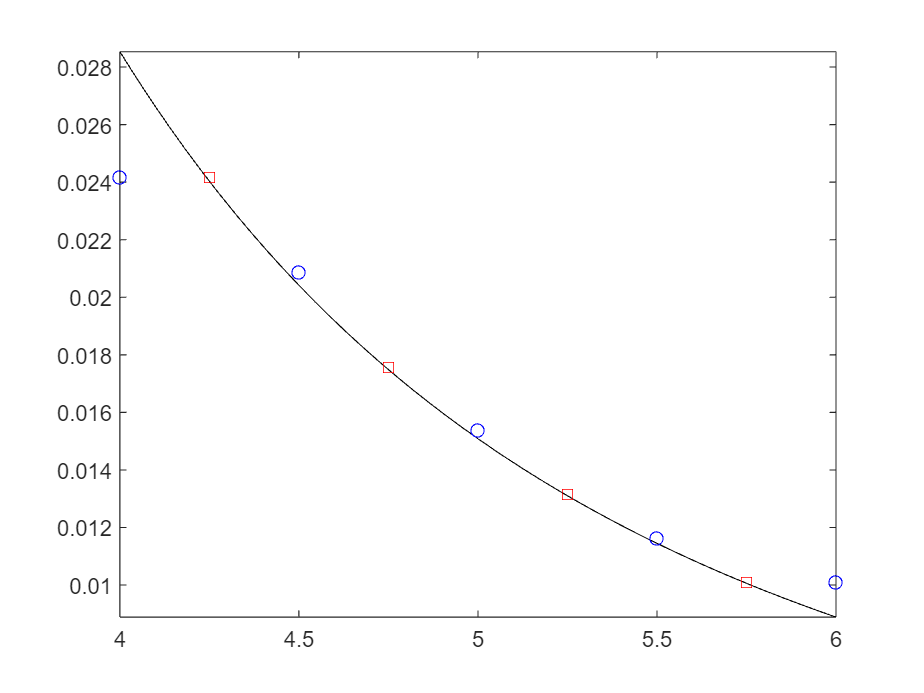

tVals = linspace(4, 6, 5);
vetVals = v(tVals);

df_grad = gradient(vetVals,tVals);

df_diff = diff(vetVals)./diff(tVals);
t_diff = (tVals(1:end-1)+tVals(2:end))/2;

fplot(acceration,[4 6],'k')
hold on
plot(t_diff,df_diff,'rs',tVals,df_grad,'bo')